# Control de fuerzas externas

# Robot Colaborativos (Cobots)

Dificultad: Alta (Avanzado)

## Teoría: Dinámica de un robot

- La dinámica de un robot tiene la siguiente expresión


$$T=M(q)\ddot{q}+C(q,\dot{q})\dot{q}+F({\dot{q})+G(q)+J(q)'F_{ext}$$


- $T$ es el par en cada eje articular.

- $M(q)$ es la matriz de inercias de cada eje

- $C(q,\dot{q})$ es matriz de Coriolis

- $F(\dot{q})$ es la fuerza de fricción

- $G(q)$ es el efecto de la gravedad

- $F_{ext}$ es las fuerzas externas, donde $J(q)$ es el Jacobiano.

#### Dinámica directa

- Obtener $\ddot{q}$ a partir de $\{T,q,\dot{q},F_{ext}\}$aplicando la formula

#### Dinámica inversa

- Obtener el par $T$ de cada articulación a partir de $\{q,\dot{q},\ddot{q},F_{ext}\}$.

### Definir el robot irb120

% Posición inicial
deg= pi/180;
mm= 1e-3;

modelo= 'D30S1_Irb120_qLC';

% Posición inicial del robot y rastreador
q0_= [0, 0, 0, 0, 0, 0]*deg;
pose_= rand(3,3)*1e-3;

% Posición del robot
baseRobot= [[0,0,0]*mm, [0,0,0]*deg];


% Definición de componentes
% Icono variable
Pinza= Pieza('Pinza_Completa');
Pinza.Base([[0,0,0]*mm, [90,0,0]*deg]);
Pinza.Tcp([[0,0,70]*mm, [0,0,0]*deg]);
masa= 1;
cdg= [0,0,0];
inercia= [1,1,1]*1e-3;
Pinza.Din(masa, cdg, inercia)
Pinza.Color([0.4,0,0.4,0.7]);

% Icono variable
Carga= Pieza('Lapiz');
Carga.Base([[0,0,0]*mm, [0,0,0]*deg]);
Carga.Tcp([[0,0,148]*mm, [0,0,0]*deg]);
masa= 1;
cdg= [0,0,0];
inercia= [1,1,1]*0e-3;
Carga.Din(masa, cdg,inercia);
Carga.Color([0.4,0,0.7,0.7]);


Kq= diag(1e3*ones(1,6));
Kw= diag(1e1*ones(1,6));
Kf= diag(1*ones(1,6));
%Ts= 1e-4; % Si fuera discreto

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
robot= importrobot(modelo);
robot.showdetails

--------------------
Robot: (10 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08          fixed            Body07(7)   Body09(9)  
   9        Body09        Joint09          fixed            Body08(8)   Body10(10)  
  10        Body10      


bodyTool= 'Body10';
q0= zeros(1,6);
rob= Cin(robot,modelo,bodyTool,q0);

Herramienta: Body10
Simulación. Ts= 0.100 m/s


### Obtener la dinámica inversa de un problema de forma simulada

- Se fija un punto $q$ deseado se simula y se mide el par que debemos usar para llegar a él.

- Comprobar que es la misma que se obtiene con las ecuaciones.

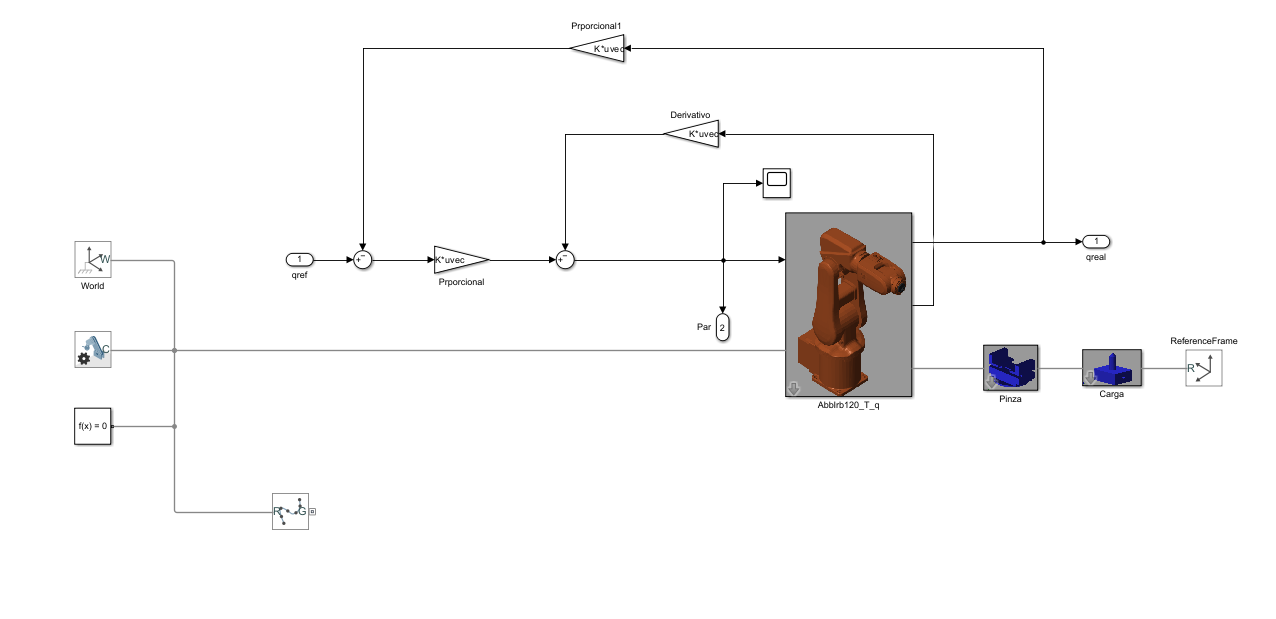

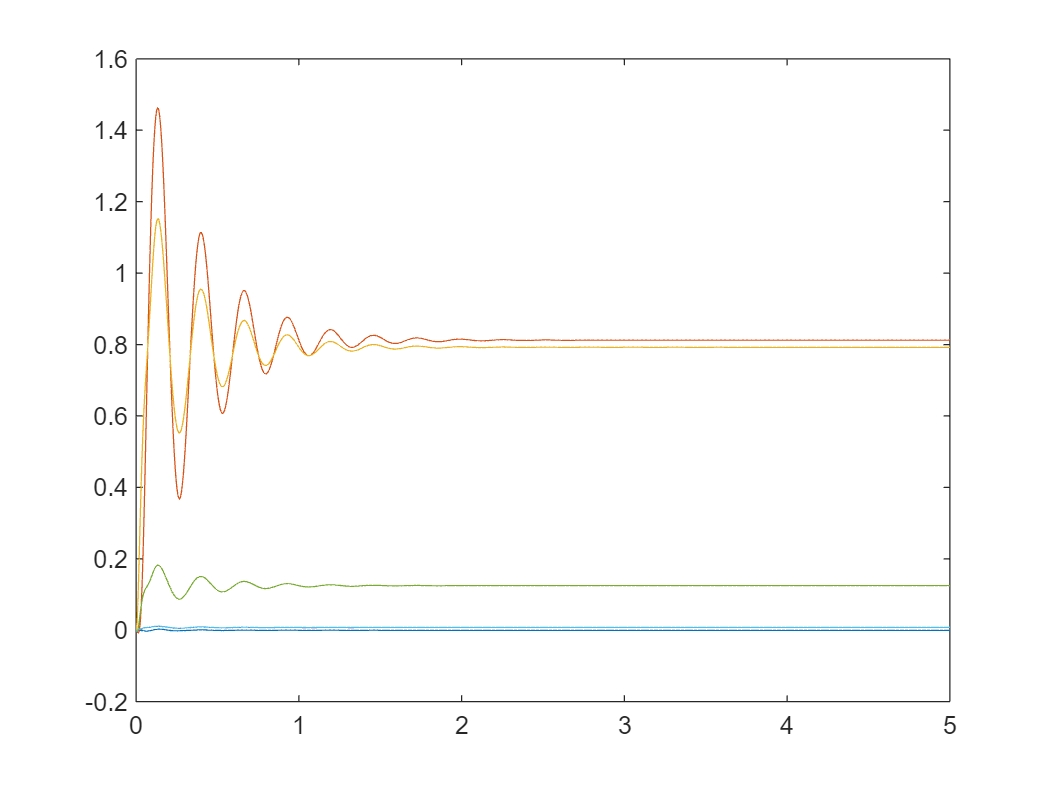

% Tiempo y movimiento de ejes
nPts= 1e3;
tend= 5;
t= linspace(0,tend,nPts)';


% Entrada en la posición de equilibrio deseada
u= repmat(q0_, [nPts,1]);

open(modelo)
sol= sim(modelo, t, [], [t,u]);
tout= sol.tout;
qreal= sol.yout(:,1:6);
Par= sol.yout(:,7:end);

figure
plot(tout, qreal*180/pi)

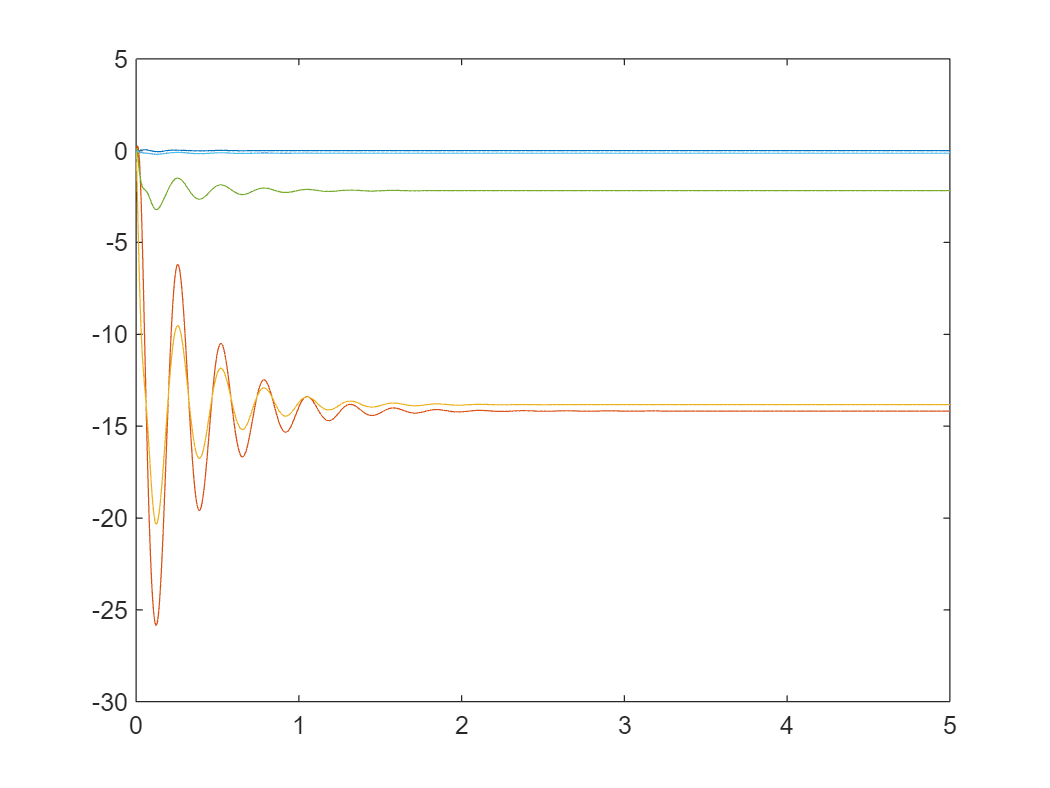

figure
plot(tout,Par)

- Par final real y estimado. Ver que la posición final no es exactamente cero.

Par(end,:)

ans =     0.0000  -14.1753  -13.8293   -0.1365   -2.1789   -0.1386


### Comparación con la obtenidas por las ecuaciones

- Es igual

rob.IDin(qreal(end,:))

ans =     0.0000  -14.1753  -13.8293   -0.1365   -2.1789   -0.1386


q_eq= qreal(end,:);
Par_eq= Par(end,:);


### Mantener al robot en la posición de equilibrio final

- Se abren los lazos para que la entrada sea el par sin realimentar

- Aguanta un rato, pero al final se cae. Parece que responde a un sistema con equilibrio inestable.

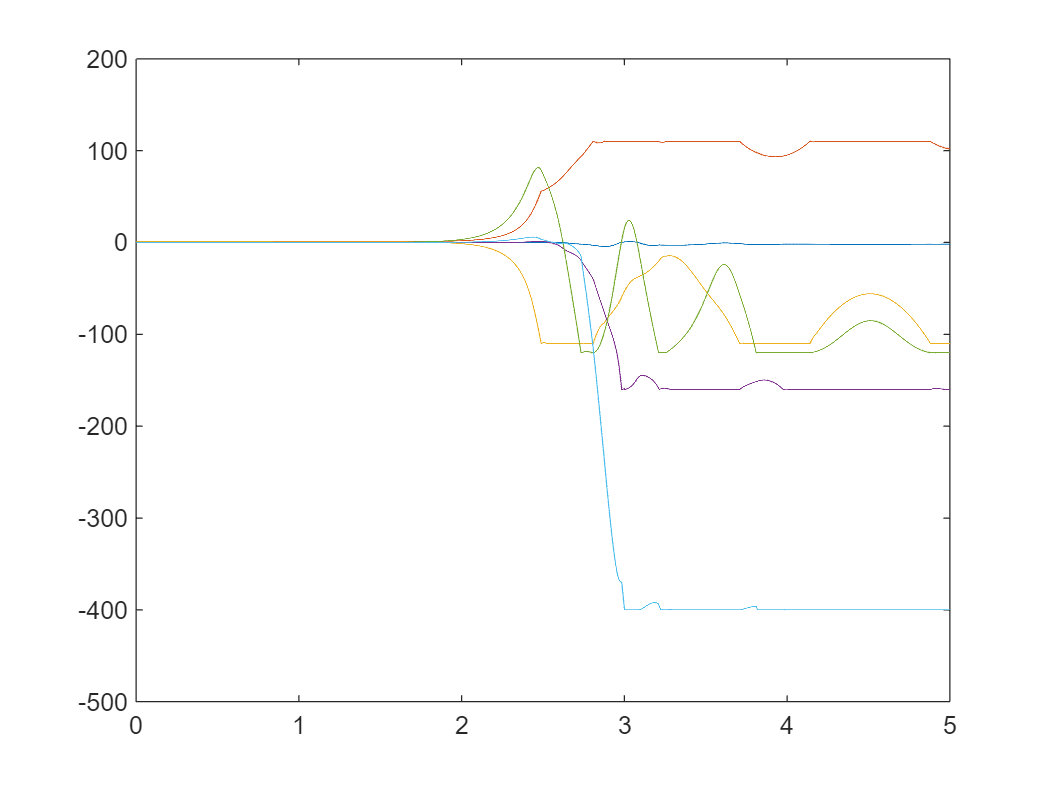

% Posición inicial

modelo= 'D30S1_Irb120_qLC';

% Gananica controladores qPD (lazo abierto)
Kp= ones(1,6);
Kd= zeros(1,6);


open_system(modelo)

% Ganancia controladores qLC (lazo abierto)
Kq= diag(ones(1,6));
Kw= diag(0*ones(1,6));
Kf= diag(0*ones(1,6));

% Para la posible realimentación
Ki= 5;
q0_= q_eq;
% Tiempo y movimiento de ejes
nPts= 1e4;
tend= 5;
t= linspace(0,tend,nPts)';
Ts= t(2)-t(1);

% Par en la posición de equilibrio final
%u= repmat(rob.IDin(zeros(1,6))',[nPts,1]);

u= repmat(Par_eq, [nPts, 1]);


sol= sim(modelo, t, [], [t,u]);
tout= sol.tout;
qreal= sol.yout(:,1:6);
Par= sol.yout(:,7:end);

figure
plot(tout, qreal*180/pi)

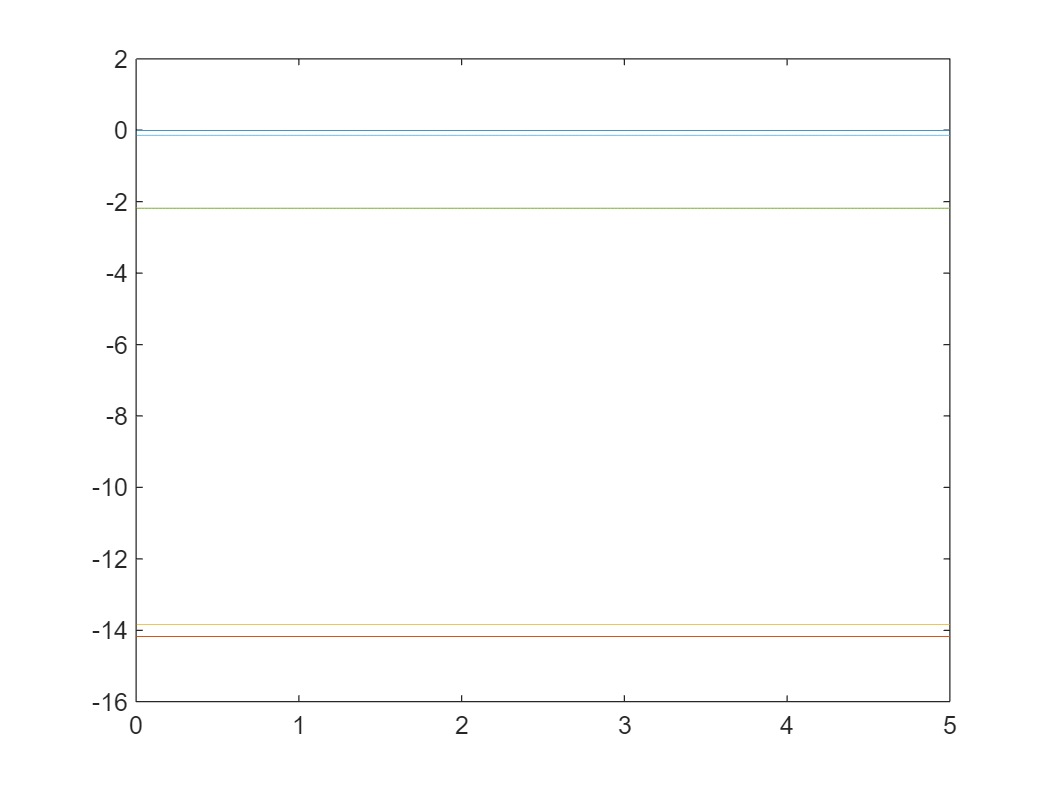

figure
plot(tout,Par)

### Detección de fuerza externa y realimentación COBOT

- Nuestro robot tiene una fuerza externa $F_{ext}$ en la TCP.

- El robot va a la posición deseada superando la fuerza externa.

- Con la dinámica inversa podemos calcular el par en cada eje correspondiente a la posición articular deseada y su derivada.

- La diferencia entre el par ideal y la real es el par que se debe realizar debido a la fuerza exterior.

- Se puede realimentar esa diferencia para que el robot se mueva por efecto de la fuerza exterior. En ese caso tenemos un robot colaborativo.

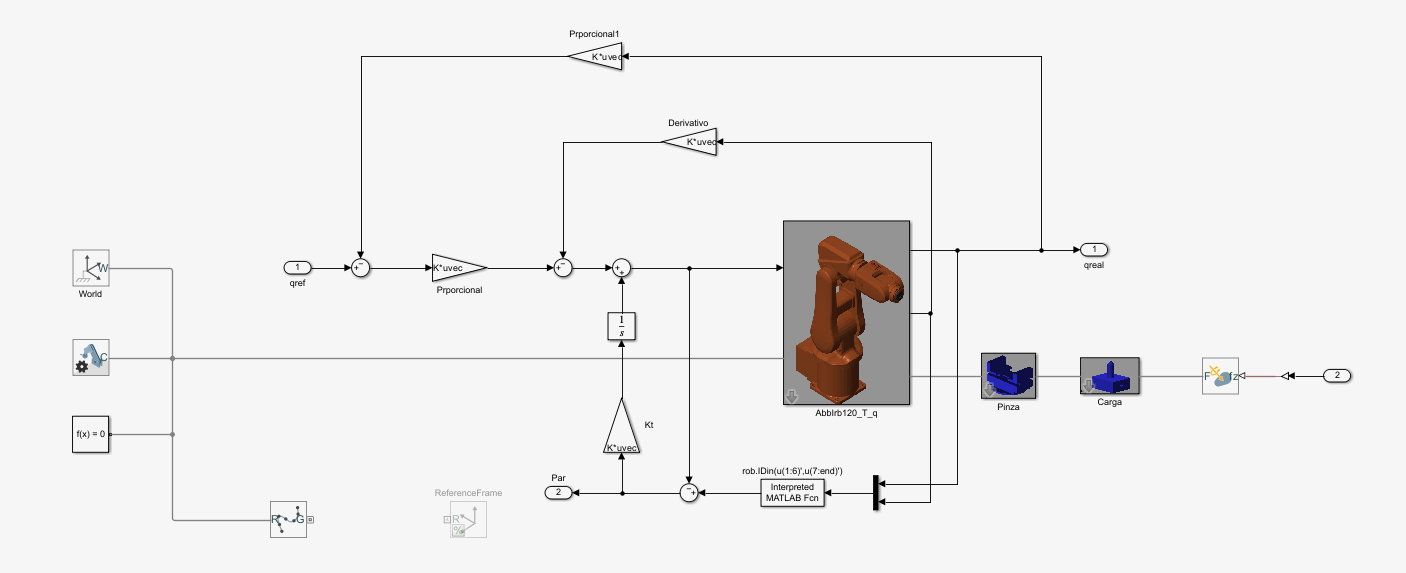

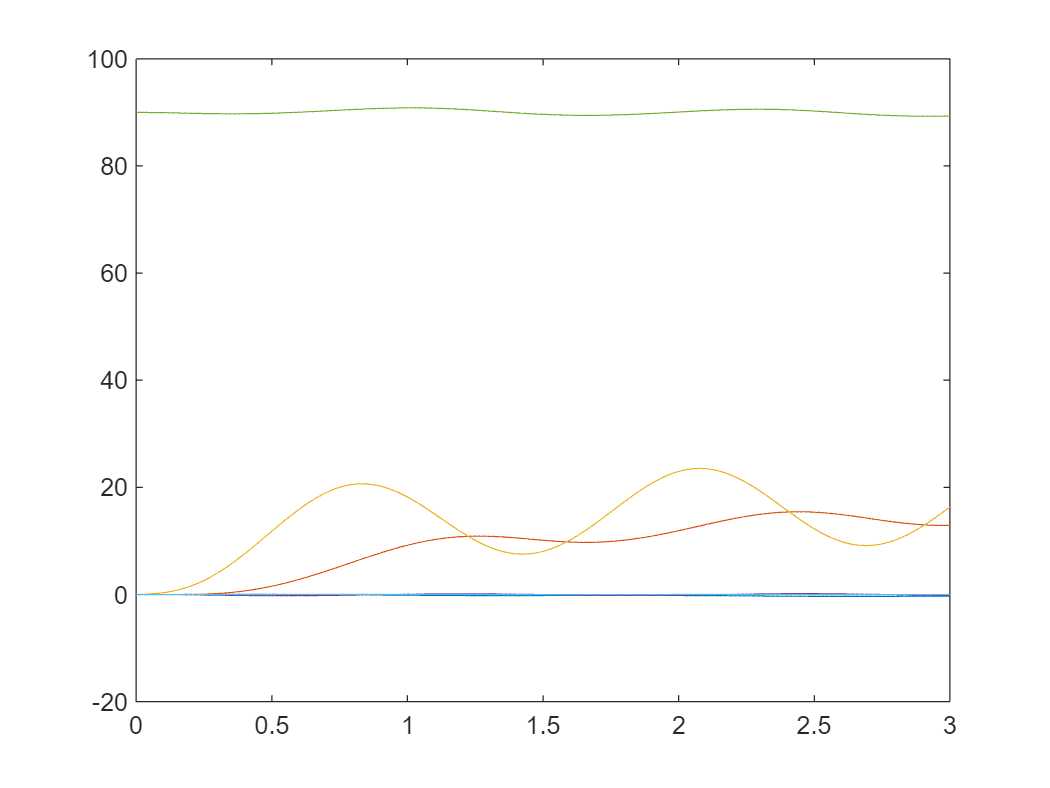

% Posición inicial

modelo= 'D30S2_Irb120_qLC_Fext';

% Posición inicial del robot y rastreador
q0_= zeros(1,6);
pose_= rand(3,3)*mm;

% Posición del robot
baseRobot_= [[0,0,0]*mm, [0,0,0]*deg];


open_system(modelo)

Kq= diag(1e3*ones(1,6));
Kw= diag(1e1*ones(1,6));
Kf= diag(1*ones(1,6));

Kt= diag(1e3*ones(1,6));

% Posición de equilibrio que se desea
q0_= [0, 0, 0, 0, 90, 0]*deg;

% Tiempo y movimiento de ejes
nPts= 1e3;
tend= 3;
t= linspace(0,tend,nPts)';

% Entrada en la posición de equilibrio deseada
q= repmat(q0_, [nPts,1]);
Fx= 5*sin(5*t);

sol= sim(modelo, t, [], [t,q,Fx]);
tout= sol.tout;
qreal= sol.yout(:,1:6);
Par= sol.yout(:,7:end);

figure
plot(tout, qreal*180/pi)

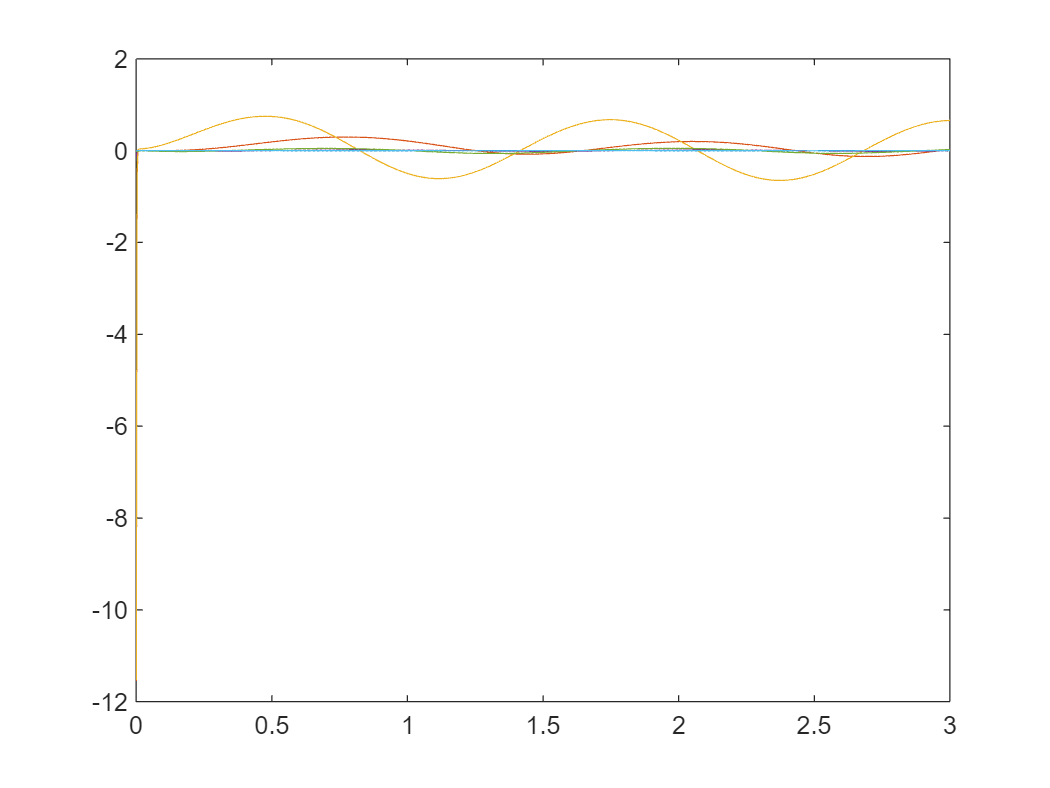

figure
plot(tout, Par)